# Object Oriented Programming (OOP)

## OOP Fundamentals

Object-oriented programming (OOP) is a programming paradigm organized around objects equipped with data fields and associated methods.

- Solver’s configuration parameters (properties) grouped with its functions (methods) into a single definition, or **class**.

- Data (state) and methods (behavior) associated via objects

- **Objects** used to interact with each other

- An object is an instance of a class. 

- Languages: C++, Objective-C, Smalltalk, Java, C#, Perl, Python, Ruby, PHP, etc.

OOP enables a level of modularity and abstraction not generally available in procedural languages:

- Increased code understanding

- Code maintenance

- Code expansion/evolution

### OOP features

- **Class**: template for creating objects, defining properties and methods, as well as default values/behavior

- **Object**: instance of a class that has a state (properties) and behavior (methods)

- **Properties**: data associated with an object

- **Methods**: functions (behavior) defined in a class and associated with an object

- **Attributes**: modify behavior of classes and class components

- **Inheritance**: object or class (subclass) derived from another object or class (superclass)

- **Polymorphism**: single interface to entities of different types (e.g. a shape superclass - triangle, rectangle, circle, etc. subclasses)

- Other OOP features, e.g. events and listeners

## OOP in MATLAB

### Class Components

#### `classdef`** block **

Contains class definition, class attributes, and defines superclasses

- *Class definitions* - blocks of code delineated with `classdef .. end `keywords

- Specify attributes and superclasses

- Contains properties, methods, events subblocks

- One class definition per file

- Only comments and blanks can precede `classdef`

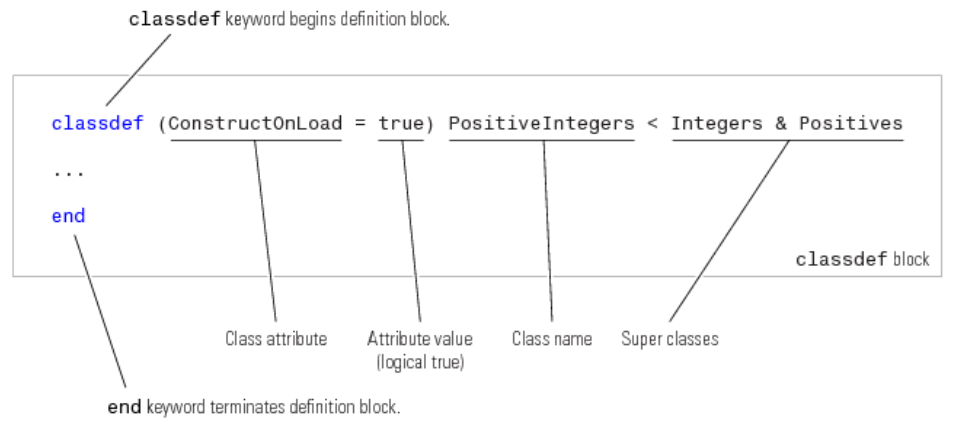

#### `properties`** block **

Defines all properties to be associated with a class instance; Defines attributes of all properties and default values

- Properties are variables associated a particular class

- Defined in special `properties` block

- Can be multiple `properties` blocks, each with own attributes

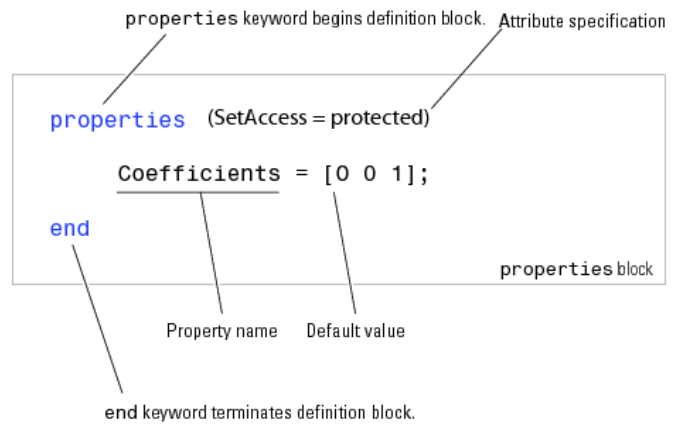

% classdef class_name
%     properties(SetAccess=private, GetAccess=public)
%         PropertyName = 'some name'
%     end
% end

obj = class_name

obj =   class_name with properties:

    PropertyName: 'some name'


obj.PropertyName

ans = 'some name'

% obj.PropertyName = 'new name'

#### `methods`** block **

Defines methods associated with the class and their attributes; First method must have the same name as the class, called the **constructor**

- Methods are MATLAB functions associated with a particular class

- Defined in special `methods` block

- Can be multiple `methods` blocks

**Constructor**

To create an instance of a class for a list of arguments, call its ***constructor***.

- By definition, the constructor is the first method in the first method block.

- It is required to have the same name as the class 

- Responsible for setting properties of class based on input arguments

- Properties not set will be given default value

- Default value either `[]` or defined in `properties` block

- Returns instance of class

`methods`

`    function obj = ClassName(arg1,arg2,...)`

`    end`

`    function some_method(obj, arg1, ...)`

`    end`

`end`

`methods (Static = true)`

`    function static_method(arg1,...)`

`    end`

`end`

`event`** block**

`enumeration`** block**

### Example: `polynomial.m`

A value class for handling polynomials of the form


$$p\left(x\right)=c_0 +c_1 x+c_2 x^2 +\cdots +c_{m\;} x^{m\;}$$


`polynomial.m`

% classdef polynomial
% %POLYNOMIAL
%     properties (GetAccess=public,SetAccess=private)
%         coeffs=0;
%         order =0;
%     end
%     methods
%         function self = polynomial(arg)
%         function [tf] = iszero(poly)
%         function [y] = evaluate(poly,x)
%         function [apoly] = plus(poly1,poly2)
%         function [mpoly] = minus(poly1,poly2)
%         function [ipoly] = integrate(poly,const)
%         function [dpoly] = differentiate(poly)
%         function [iseq] = eq(poly1,poly2)
%         function [] = plot it(poly,x,pstr,ax)
%         function [] = disp(poly)

#### Constructor

p1 = polynomial([1,2,3]) 
p2 = polynomial(p1)
p3 = polynomial([1,2,3,0])

#### Object Arrays

Similar to arrays of numbers, cells, and structures, we can define ***objects arrays*** as an array where each element is an instance, or object, of a particular class.

[polynomial([1,2]),polynomial([3]),polynomial([3,2,1])]

p1 = 1.0000 + 2.0000 x + 3.0000 x^2

p(1,7) = polynomial([1,2,3]);

p2 = 1.0000 + 2.0000 x + 3.0000 x^2

p(3)

p3 = 1.0000 + 2.0000 x + 3.0000 x^2

p(7)

#### Accessing Properties in Object

Properties are accessed using the `.` operator, similar to accessing fields in a structure.

**public vs. private properties**

- `GetAccess`, `SetAccess` define where the properties can be queried or set, respectively

- `public` properties have unrestricted access

- `protected` properties can only be accessed from within class or subclass

- `private` properties can only be accessed from within class

p1.order

ans = 1.0000 + 2.0000 x
3.0000
3.0000 + 2.0000 x + 1.0000 x^2

p2.coeffs
p(3).order

ans = 0.0000

p(7).coeffs

ans = 1.0000 + 2.0000 x + 3.0000 x^2

#### Types of Methods

- **Ordinary** methods - functions that act on one or more objects (plus additional data) and return a new object or some computed value

- **Constructor** methods - special function that creates the objects of a class

- **Destructor** methods - function called when instance of class is deleted

- **Statics** methods - functions associated with a class that do not necessarily act on class objects

All methods must accept the *class instance* as their first argument

Methods can be accessed in two main ways

- Using the `.` operator with the class instance: Implicitly passes the class instance as the first argument

- Directly passing the class instance as the first argument

p3.iszero()

ans =      2


p3.evaluate(0:0.5:1)

ans =      1     2     3


p4 = polynomial(0);

ans =      0


iszero(p4)

ans =      1     2     3


evaluate(p3,0:0.5:1)

#### Implementing Operators

- Operators such as `+, -, *, .*, ==, <, >,` etc can be overloaded for a given class

- Simply implement a method with an appropriate name and number of

- arguments: a list of operators and their corresponding names are listed here

- When operator such as `+` called, it uses the data type to determine when

- function is called

Let's implement the following methods:

`plus` to overload the + operator to return $p_3 \left(x\right)=p_1 \left(x\right)+p_2 \left(x\right)$

`minus` to overload the - operator to return $p_4 \left(x\right)=p_1 \left(x\right)-p_2 \left(x\right)$

`differentiate` to return $p^{\prime } \left(x\right)$

`integrate` to return $\int \;p\left(x\right)$

**Test polynomial class**

poly(1) = polynomial([0,3]);

ans = logical
   0


poly(2) = polynomial([-3,1,10]);

ans =    1.000000000000000   2.750000000000000   6.000000000000000


poly(3) = polynomial([9,-1,0,2]);
poly

ans = logical
   1


figure

ans =    1.000000000000000   2.750000000000000   6.000000000000000


ax=axes('nextplot','add');
for i = 1:length(poly)
    ipoly(i) = integrate(poly(i),0);
    dpoly(i) = differentiate(poly(i));
    ppoly(i) = poly(i)^2;
    uppoly(i)= +poly(i);
    umpoly(i)= -poly(i);
    eval0(i) = evaluate(poly(i),0);
    zpoly(i)= iszero(poly(i));
    for j = 1:length(poly)
        apoly(i,j) = poly(i) + poly(j);
        mpoly(i,j) = poly(i) - poly(j);
        tpoly(i,j) = poly(i)*poly(j);
    end
    plot_it(poly(i),linspace(-1,1,100),{'-','linewi',2},ax); 

poly = 0.0000 + 3.0000 x
-3.0000 + 1.0000 x + 10.0000 x^2
9.0000 + -1.0000 x + 0.0000 x^2 + 2.0000 x^3

end
plot_it(mpoly(2,3),linspace(-1,1,100),{'-.','linewi',1.5},ax);
plot_it(tpoly(1,2),linspace(-1,1,100),{'-.','linewi',1.5},ax);
plot_it(ppoly(2),linspace(-1,1,100),{'-.','linewi',1.5},ax);
plot_it(dpoly(2),linspace(-1,1,100),{'-.','linewi',1.5},ax);
plot_it(ipoly(2),linspace(-1,1,100),{'-.','linewi',1.5},ax);
ylim([-20,40]);
legend('$p_1=3x$','$p_2=-3+x+10x^2$','$p_3=2x^3-x+9$',...
    '$p_2-p_3$','$p_1\times p_2$','$p_2^2$','$dp_2/dx$','$\int p_2$','Interpreter','latex');

close all; clear; clc

### Value vs. Handle Class

Two fundamentally different types of classes in MATLAB

An instance of a **value** class behaves similar to most MATLAB objects

- A variable containing an instance of a value class owns the data associated to it

- Assigning object to new variable copies the variable

Conversely, an instance of a **handle** class behaves similar to MATLAB graphics handles

- A variable containing an instance of a handle class is a reference to the associated data and methods (similar to graphics handles as references to graphics objects)

- Assigning object to a new variables makes a new reference to same object Events, listeners, dynamic properties

- In contrast to value classes, ***handle*** classes enable you to create an object that more than one function can share

- Declare class a handle class by having it inherit from the handle `superclass`

- Similar to value classes, the first argument of all methods must be the class instance itself, and methods are invoked identically.

- Unlike value classes, a method in a handle class can modify properties of the class instance

- Removes need for instantiating new objects and returning them in methods: a method can simply modify the properties of the instance in place and does not necessarily require an output.

- More on handle class here: [http://www.mathworks.com/help/matlab/handle-classes.html](http://www.mathworks.com/help/matlab/handle-classes.html)

### Handle Class Example: `element.m`

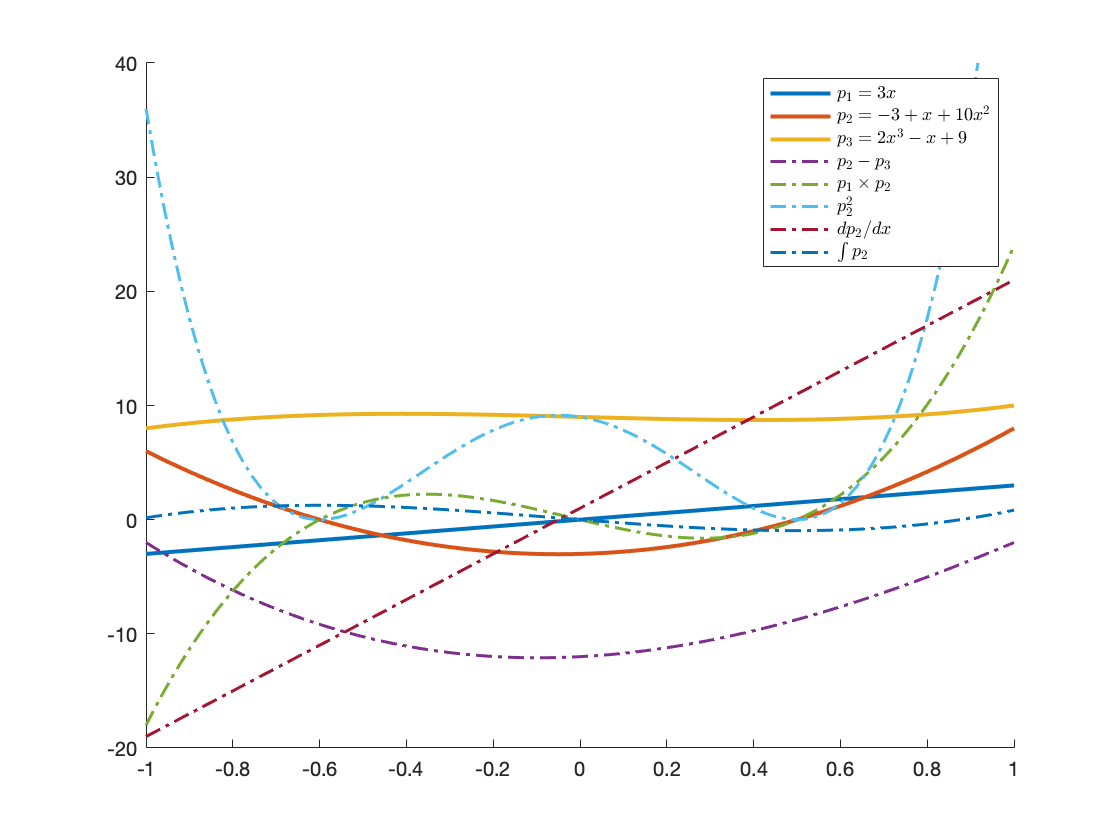

e2 =   element with properties:

            nsd: 2
         nedges: 3
          nodes: [2×3 double]
    elementType: 'Triangle'


e1 =   element with properties:

            nsd: 2
         nedges: 3
          nodes: [2×3 double]
    elementType: 'Rectangle'


ans = 'Rectangle'

e2 =   handle to deleted element


e1 = element;
e2 = e1
e1.elementType = 'Rectangle'
e2.elementType
delete(e1) % call destructor
e2